# Senzory a Měření - protokol - optické senzory polohy

Vypracoval **Vojtěch Michal** 15. dubna 2021, "měření" provedeno dle videí ze dne 25. 3. 2020.

Záznam z měření na Youtube:

[https://www.youtube.com/watch?v=K6_d7-hPUjI](https://www.youtube.com/watch?v=K6_d7-hPUjI) [https://www.youtube.com/watch?v=l4pNdkeAvxE](https://www.youtube.com/watch?v=l4pNdkeAvxE) [https://www.youtube.com/watch?v=xkRTL7l4hdc](https://www.youtube.com/watch?v=xkRTL7l4hdc) [https://www.youtube.com/watch?v=D9uuq498mqg](https://www.youtube.com/watch?v=D9uuq498mqg)

Návod k úloze je na https://moodle.fel.cvut.cz/pluginfile.php/279151/mod_folder/content/0/04_Opticky_senzor_polohy_2021_1.pdf

## Domácí příprava

Obrázky a schémata, na které se úkoly odkazují, jsou k nalezení v zadání.

- Jaký je vstupní odpor převodníku I – U dle obr. 1 a jak určíte velikosti proudu $I_{FD1}$ z napětí $U_{OZ}$? Navrhněte převodník proud-napětí s OZ, který proud 100uA z fotodiody převede na výstupní napětí 1V. Schéma zakreslete. Jaký je výstupní odpor převodníku? **Odpověď: **Převodník I->U má vstupní odpor $R_{in} = 0\Omega$, výstupní odpor $R_{out} \to \infty$, pro výstupní napětí platí $U_o = -I \cdot R_Z$. Pro požadovaný převod tak lze použít $R_z = 10\text{k}\Omega$.

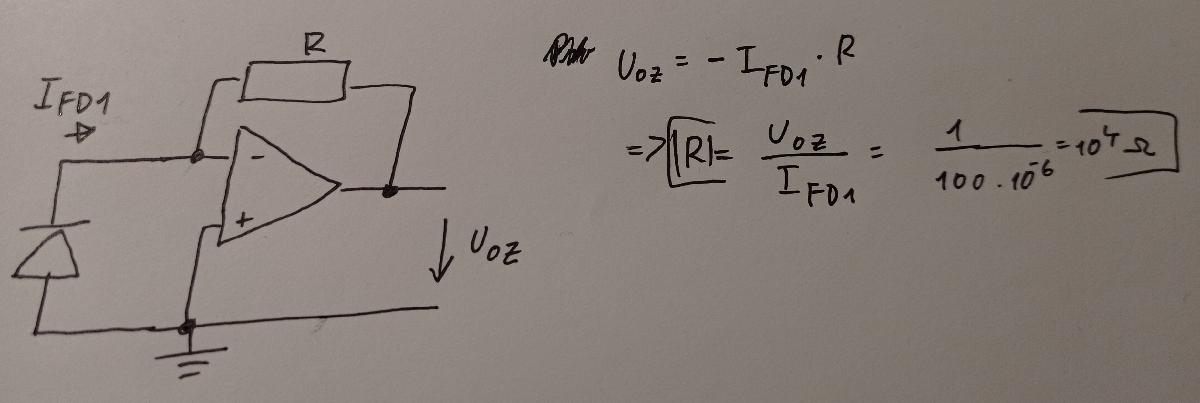

- Fotodioda má vnitřní odpor 8 kOhmů. Chová se jako napěťový nebo proudový zdroj? Jaké bude výstupní napětí, pokud výstup fotodiody naprázdno je 0,5V a a) zatěžujeme odporem 80 kOhm. b) odporem 8 kOhm. **Odpověď: **Vysoký vnitřní odpor ukazuje na velice měkký zdroj napětí, řekl bych skoro až nepoužitelný pro jakékoli větší zatížení. Dioda je vhodnější jako zdroj proudu. Při zatížení vnějším odporem vzniká napěťový dělič. Při zatížení (a) je dělení 1 : 10, při (b) je dělení 1 : 1, výstupní napětí tak budou $0.5 \cdot \frac{80k}{8k + 80k} = 0.45V$ a 0.25 V.

- Jak byste určili vnitřní odpor fotodiody, pokud byste ho neznali? A jak byste určili vnitřní odpor olověného 12V akumulátoru (zkuste použít metodu, která bude fungovat pro oba případy). **Odpověď:** Zatěžovací přímka je popsána napětím naprázdno a zkratovým proudem. Zkratovat svorky olověného akumulátoru a měřit stovky A zkratového proudu není úplně moudrý nápad. Jistě ale lze v okolí pracovního bodu změřit několik párů (U, I) a jimi proložit charakteristiku. Stejně se u reálných součástek projeví nelinearity, takže lokální měření bude mít větší vypovídací hodnotu.

- Jaké hlavní nectnosti má jednoduchý optický reflexní snímač polohy? Proč se používá modulace světelného zdroje a průměrování? **Odpověď: **V první řadě je problematická závislost na odrazivosti detekovaného objektu a vliv okolního světla. Vliv okolního světla (silných 100 Hz ze žárovek a dále napříč celým spektrem rozložené sluneční záření) lze potlačit právě modulací a chytrým zpracováním signálu. Spínání svítícího prvku (třeba LED) na pevné vyšší frekvenci zesnadňuje následnou filtraci ostatního bordelu a současně to umožňuje i krátkodobé přetěžování LED. Každá součástka má omezení na ztrátový výkon, který zvládne uchladit. Když se svítí jen v krátkých pulzech, může se použít vyšší proud (zajišťující vyšší intenzitu záření a tedy dosvit na větší vzdálenost) bez nebezpečí upečení součástky.

- Co je hlavní výhoda triangulačního snímače vzdálenosti? Nakreslete princip činnosti triangulačního snímače. K čemu je tam fotodioda "PSD"? Jak je v triangulačním snímači vzdálenosti zajištěno, že nereaguje na rušivé okolní světlo? **Odpověď: **Triangulační snímač netrpí žádným ze dvou základních problémů, které měl třeba klasický reflexní snímač. Vliv vnějšího světla lze potlačit - použije se IR vysílač a před PSD přijímač se umístí filtr odstraňující vše vyjma IR. Základní vlastnost je ale značná nezávislost na odrazivosti objektů. Paklliže se odraží alespoň nějaké světlo, není pro PSD příliš důležité, v jaké intenzitě záření dopadlo. Stěžejní je, že dopadlo právě na jedno místo a všude kolem vůebc nebo výrazně méně. Na obrázku níže je načrtnut princip fungování senzoru - vysílaný paprsek (případně ještě fokusovaný čočkou u LEDky) letí vzduchem a v nějakék vzdálenosti se odrazí od detekovaného objektu. Na jeho povrchu nastanou difuzní odrazy do všech směrů (povrch není dokonale hladký) a jedním ze směrů je i směr právě do čočky na PSD snímači, který je bokem a pod úhlem vůči LED. Určením bodu na PSD, jenž byl dopadajícím světlem ozářen, a troškou trigonometrie (prakticky spíše lookup tabulkami) se určí vzdálenost, ve které byla umístěna odrazná plocha.

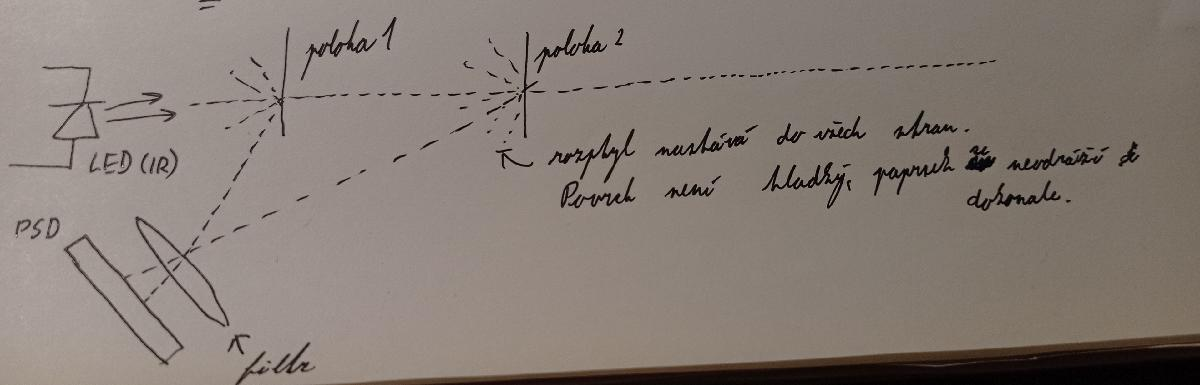

## Poznámky

K osciloskopu existují speciální sondy s fotodiodou na konci, například vhodné pro analýzu modulace senzorů založených na vysílání světla.

Optické senzory je vhodné vyrábět s optickými vlákny - veškerá vyhodnocovací elektronika je v krabičce "někde dál", do vysílače a přijímače směřují pouze optická vlákna. Tok světla v optickém vlákne nelze běžnou EMI narušit, dále je-li vlákno z rozumně odolného materiálu, je řešení velice robustní po mechanické i tepelné stránce. Účel senzoru je určen m.j. fyzickým uspořádáním vysílače a přijímače - třeba optická závora (detekce průchodu objektů) a nebo klasický reflexní senzor (měření vzdálenosti objektu). Do jisté míry by asi šlo použít i pro triangulační senzor (minimálně pro dostání světla do vysílače), ale protože citlivý prvek je PSD, které má elektrický výstup, není možné světlo odvést do vzdálené vyhodnocovací jednotky - v případě přítomnosti EMI musí být vyhodnocovací logika poblíž.

Optická brána může být užitečná i při klasifikaci objektů na výrobní lince - šrouby, vrtáky atp. Jiná hodnota čtení ze senzoru, než je pro danou třídu objektů očekávána, bude indikovat, že se pomíchaly šrouby dohromady.

Velký význam mají senzory s polarizací světla - průmyslové vylepšení např optické brány. Na jedné straně je vysílač emitující polarizované světlo. Na druhé straně je speciální odrazka otáčící rovinu polarizace o 90°. Před přijímačem je polarizační filtr odstraňující všechny ostatní orientace. Pakliže je do cesty světlu vložen jiný objekt, nastane difuzní odraz, jenž kompletně naruší polarizaci a závora detekuje "zastínění". Lidským okem ale není rozdíl patrný - na odrazce i na případném zakrývacím objektu je stejná červená tečka. Rozdíl se pozná jen v polarizaci daného světla. Díky polarizaci je senzor odolný proti okolnímu osvětlení.

## (A) Měření parametrů fotodiody

### 1) Změřte velikost výstupního signálu fotodiody a napětí na ní


IRED = [12; 8; 4; 0];
%Na videu nebylo měření pro IRED = 0mA, příslušná políčka označuje NaN
U_OZ_video = [9.265; 6.019; 2.76; NaN];
U_OZ_laborky = [9.381; 6.262; 3.075; 0];
%Napětí na fotodiodě naprázdno
U_FOT_video = [-0.460; -0.441; -0.411; NaN];
U_FOT_laborky = [-0.403; -0.446; -0.42; 0.025];
% Dle očekávání je velmi stabilní napříč různými proudy

OutputVoltages = array2table([IRED, U_OZ_video, U_OZ_laborky], 'VariableNames', {'IRED [mA]', 'U_OZ (video) [V]', 'U_OZ [V]'})

OutputVoltages = 4×3 table
    IRED [mA]    U_OZ (video) [V]    U_OZ [V]
    _________    ________________    ________
       12             9.265           9.381  
        8             6.019           6.262  
        4              2.76           3.075  
        0               NaN               0  

DiodeVoltages = array2table([IRED, U_FOT_video, U_FOT_laborky], 'VariableNames', {'IRED [mA]', 'U_FOT (video) [V]', 'U_FOT [V]'})

DiodeVoltages = 4×3 table
    IRED [mA]    U_FOT (video) [V]    U_FOT [V]
    _________    _________________    _________
       12              -0.46           -0.403  
        8             -0.441           -0.446  
        4             -0.411            -0.42  
        0                NaN            0.025  

Na datech je patrná velmi dobrá korespondence s očekáváním - rostoucí proud IRED znamená vyšší intenzitu svitu vysílače, díky které lze očekávat vyšší proud (převedný následně na měřené napětí) fotodiodou. Z modelu vystupuje hodnota $U_{FOT}$ z měření na laborkách pro IRED = 12mA, nastala zřejmě systematická chyba - například zeslabení optické vazby mezi vysílačem a přijímačem. Voltampérová charakteristika diody ve fotokonduktivím režimu by ideálně měla být monotonní; správně by proto nemělo napětí v propustném směru s vyšším osvícením (a vyšším proudem) poklesnout.

### 2) Určení vnitřního odporu $R_3$ v zapojení (viz zadání Obr. 1)

Napětí na výstupu zesilovače naprázdno je 9.245 při měření naprázdno (zatíženo pouze vysokým vnitřním odporem voltmetru). Při připojení zátěže $R_{load}$=80 k$\Omega$ poklesne měřené napětí na 8.2 V. Zbytek odvození viz obrázek:

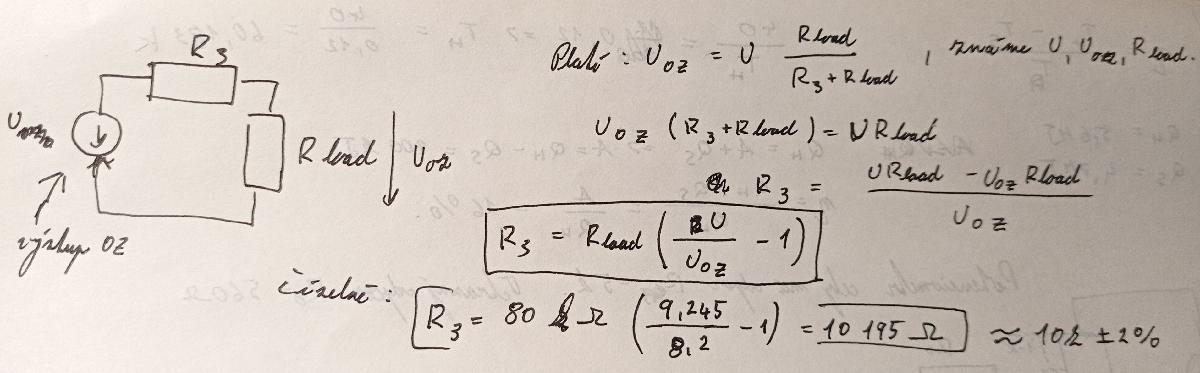

Hodnota vnitřního odporu $R_3$ je 10k$\Omega$. Experimentální ověření spočívá v nastavení $R_{load} = R_3$ a ověření, že $U_{OZ} = \frac{U}{2}$.

## (B) Optoelektronické snímače polohy

### 1.1) Určete závislost výstupního signálu na vzdálenosti u reflexního snímače s optickými vlákny

ReflexSensor = readtable('data-opt-reflex.csv')

ReflexSensor = 8×2 table
    mm    count
    __    _____
     5    2701 
    10    1430 
    15     886 
    20     601 
    25     431 
    30     327 
    40     205 
    60     102 

data = table2array(ReflexSensor);
distance = data(:, 1);
counts = data(:, 2); % čtení je ve kvantech reflexního senzoru

% Fit pomocí Matlabovské funkce
fit_matlab = fit(distance, counts, 'power1')

fit_matlab =      General model Power1:
     fit_matlab(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =   1.584e+04  (1.203e+04, 1.966e+04)
       b =      -1.088  (-1.209, -0.9671)

%aproximuje data průběhem 15840* x^{-1.088}
fit_matlab = fit_matlab(distance);
fit_trial_error = 14300 ./ (distance-1) - 150;

%Vykreslení grafů (pozor, graf se může posunout dost dolů v generovaném PDF!)
plot(distance, fit_matlab);
hold on;
plot(distance, fit_trial_error);
stem(distance, counts);
xlabel('Vzdálenost odrazné plochy [mm]');
ylabel('County senzoru [-]');
legend('Proložení Matlabem', 'Proložení odhadem', 'Naměřená data', 'location', 'northeast');
title('Charakteristika reflexního senzoru');

Chrakteristika je rozhodně klesající, od oka se dá obstojně proložit funkcí $counts(x) = \frac{14300}{x-1} - 150$ pro $x \cdots$vzdálenost objektu v milimetrech. Tento odhad je dokonce přesnější pro vyšší hodnoty $x$ (od 10mm dál) než fit Matlabem.

### 1.3) Změřte vlastnosti modulace optického signálu ve snímačích polohy.

Pro refexní senzor i světelnou závoru (obojí je stejná vyhodnocovací jednotka, z níž je optickými vlákny světlo vyvedeno k vysílači a přijímači): 2 $\mu$s dlouhé pulsy s periodou $T = 100 \mu$s; to je střída 2%. Obojí je světlo viditelné.

Pro triangulační senzor (IR) je puls široký 125 $\mu$s, perioda cca $T = 1$ms; střída 12.5%. Pulsy na výstup vychází po skupinách - vnitřně je senzor digitální a analogový signál na výstup generuje "ručně". Použije proto celou skupinu světelných pulsů pro změření vzdálenosti objektu a po konci skupiny skokově změní výstup. Při prudké změně polohy tak lze pozorovat na výstupu senzoru schody, jak senzor přebíhá z jedné úrovně na druhou.

Reflexní senzor s polarizací: 18 $\mu$s šířka pulsu, perioda $T = 200\mu$s.

### 2) Triangulační snímač

Použitý triangulační snímač je Sharp GP2Y0A21YK0F (datasheet [https://www.pololu.com/file/0J85/gp2y0a21yk0f.pdf).](https://www.pololu.com/file/0J85/gp2y0a21yk0f.pdf).) Na straně 5 datasheetu je následující charakteristika

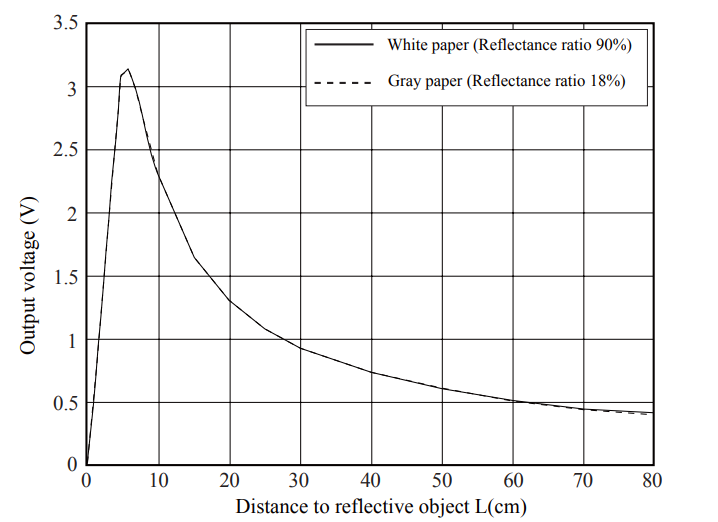

Je patrný peak na vzdálenosti cca 5cm. Pro rostoucí vzdálenost výstup poklesá možná nepřímo úměrně. Při prokládání se zaměřím právě na tuto oblast, katalogová data ověříme následujícím měřením:

TriangSensor = readtable('data-opt-triang.csv')

TriangSensor = 14×2 table
    mm      V  
    ___    ____
      5    1.25
     10    1.68
     15    1.59
     20    2.62
     25    2.93
     30    3.02
     40    3.15
     60    3.12
     80    2.59
    100    2.18
    150    1.57
    200    1.25
    250    1.04
    300    0.88

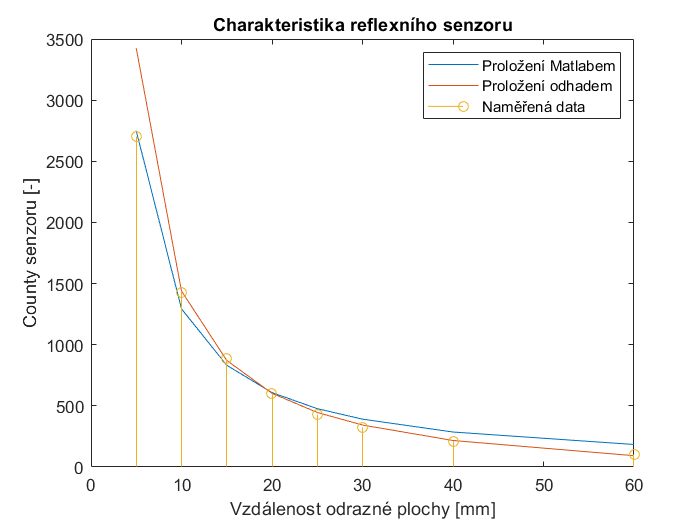

fit_matlab =      General model Power1:
     fit_matlab(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =       12.61  (11.36, 13.85)
       b =     -0.7703  (-0.814, -0.7266)

data = table2array(TriangSensor);
distance = data(:, 1) / 10; %převod mm na cm
voltage = data(:, 2); % čtení je ve voltech

%Očekávám zlom charakteristiky kolem vzdálenosti 5cm, proto pro prokládání
% vyfiltruji jen data z větší vzdálenosti.
distances_more_than_5 = distance(distance >= 5);
voltages_more_than_5 = voltage(distance >= 5);

% Fit pomocí Matlabovské funkce
fit_matlab = fit(distances_more_than_5, voltages_more_than_5, 'power1')

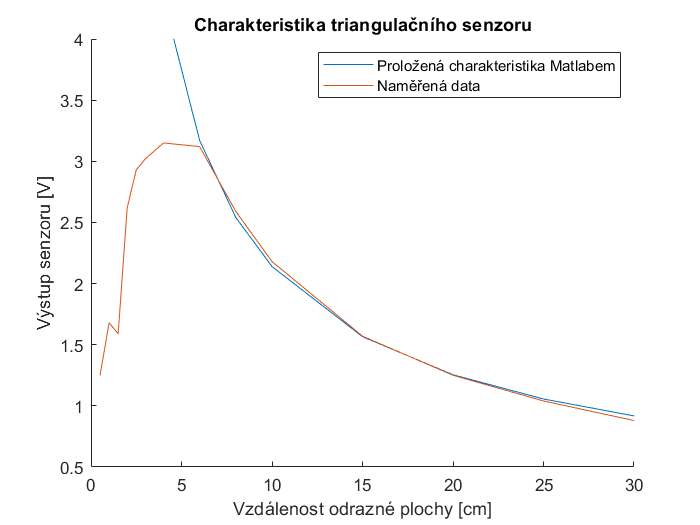

%aproximuje data funkcí 15840* x^{-1.088}
fit_matlab = fit_matlab(distance);

%Vykreslení grafů
figure
hold on;
plot(distance, fit_matlab);
plot(distance, voltage);
ylim([0.5 4]); %omezení rozsahu na ose y, protože jinak by
% fit_matlab vybouchnul do vysokých čísel
xlabel('Vzdálenost odrazné plochy [cm]');
ylabel('Výstup senzoru [V]');
legend('Proložená charakteristika Matlabem', 'Naměřená data', 'location', 'northeast');
title('Charakteristika triangulačního senzoru');

Charakteristiky se velmi dobře shodují. Pro vzdálenosti vyšší jak 5cm lze data s velkou přeností proložit funkcí $voltage(x) = \frac{12.61}{x^{0.77}}$, kde $x$ je vzdálenost měřeného objektu v centimetrech. Extrapolujeme-li touto funkcí charakteristiku i pro menší vzdálenosti, objeví se obrovská chyba -  na grafu je průběh omezen na hranici 4V, ale ve skutečnosti pokračuje až k hranici 30V.